# **Review of Numerical Programming - for Final Exam**

**by Y.-K. Kim**

## Procedure

- Solve the following problems using MATLAB’s functions

- Then, solve using your NM library in C and compare answers

# Linear Regression

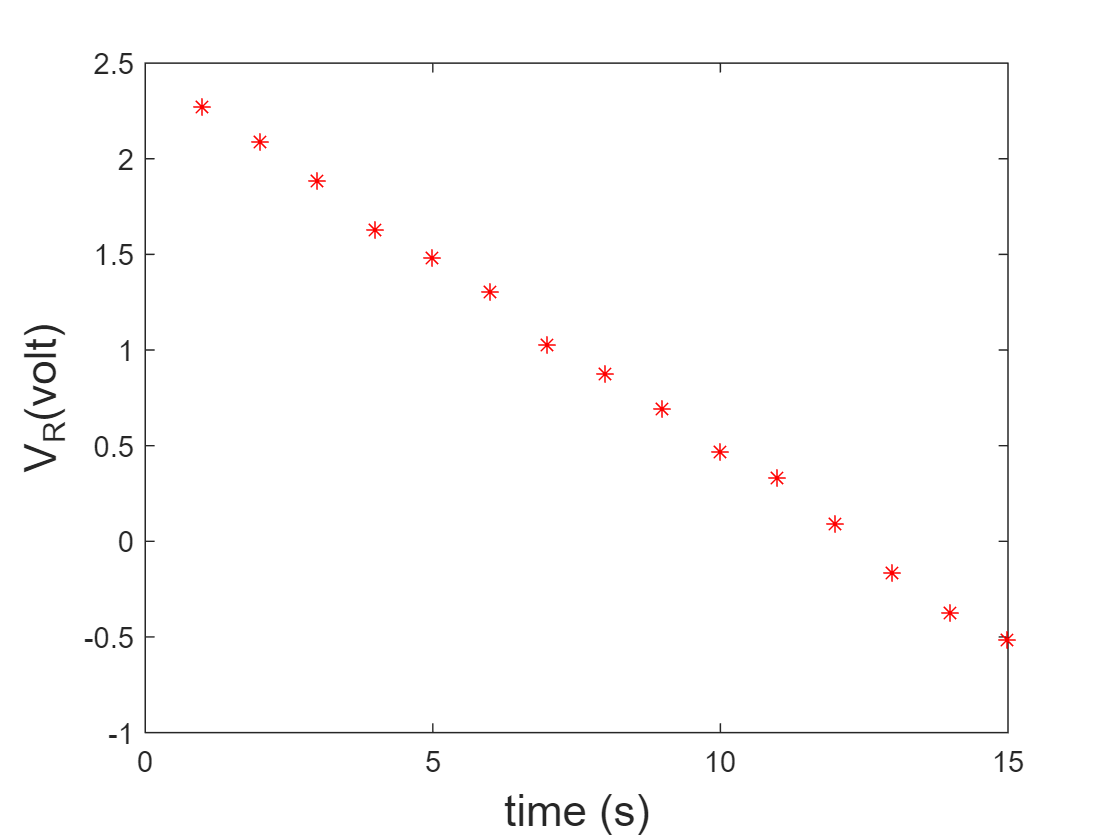

t = 1:1:15;
V=[2.272	2.092	1.887	1.629	1.482	1.308	1.030	0.875	0.693	0.470	0.336	0.095	-0.163	-0.371	-0.511];

figure
plot(t,V, '*r')
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)


% Matlab function
Zopt=polyfit(t,V,1);
Yopt=polyval(Zopt,t);  % Matlab function

Yopt_temp=Zopt(2)+Zopt(1)*2  % Matlab function

Yopt_temp = 2.0770

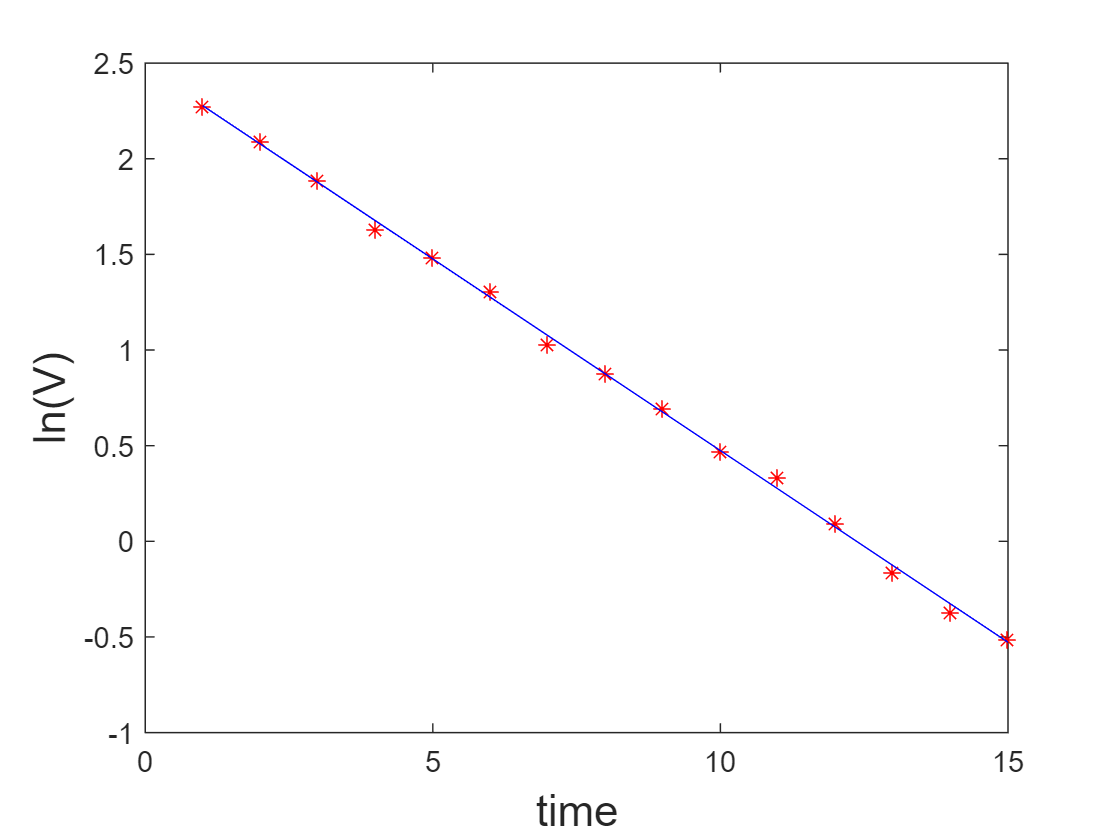


figure
plot(t,V, '*r')
hold on
plot(t,Yopt, '-b')
xlabel('time','fontsize',15)
ylabel('ln(V)','fontsize',15)

# Exponential Fitting

RC circuit with unknown capacitor C and resistor of 5M$\Omega$

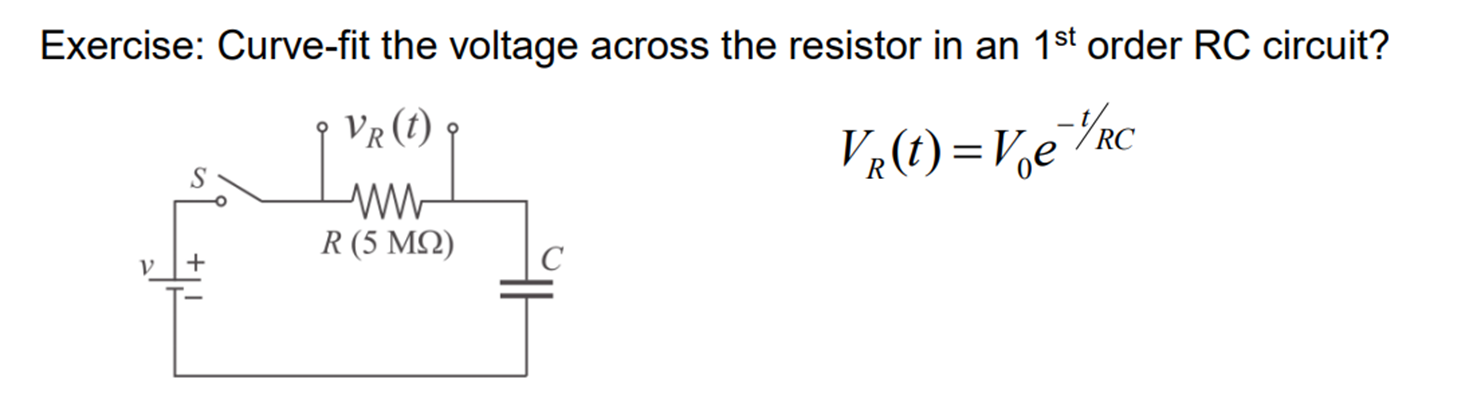

a) Find the capacitance  C from curve fitting

b) Esimate the voltage when time=32sec

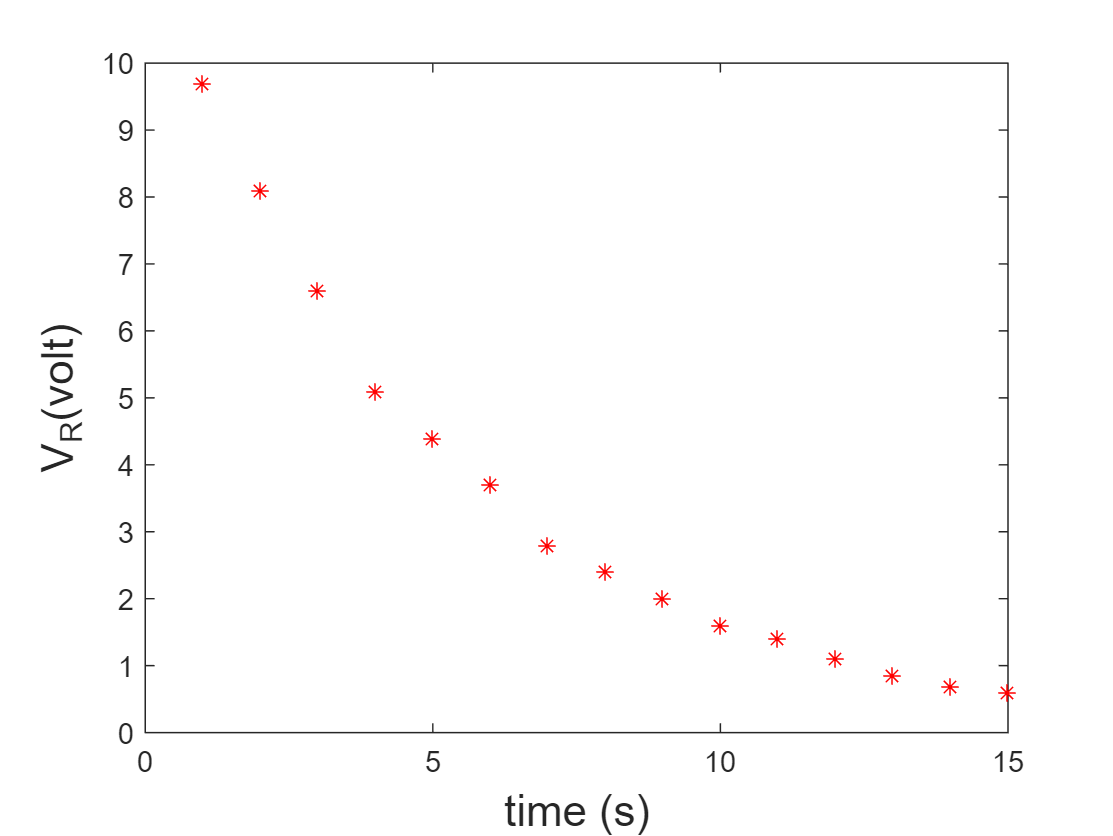

Xdata = 1:1:15;
Ydata = [9.7 8.1 6.6 5.1 4.4 3.7 2.8 2.4 2.0 1.6 1.4 1.1 0.85 0.69 0.6];
R=5e6;

figure
plot(Xdata,Ydata, '*r')
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)

% V=V0 exp(-1/(RC)*t)
%
% ln(V)=ln(V0)-1/(RC)*t
% y=a0 + a1*t
%
% V=exp(y)
% V0=exp(a0);
% (RC)=-1/a1;

% Matlab function
Zopt=polyfit(Xdata,log(Ydata),1)

Zopt =    -0.2003    2.4776


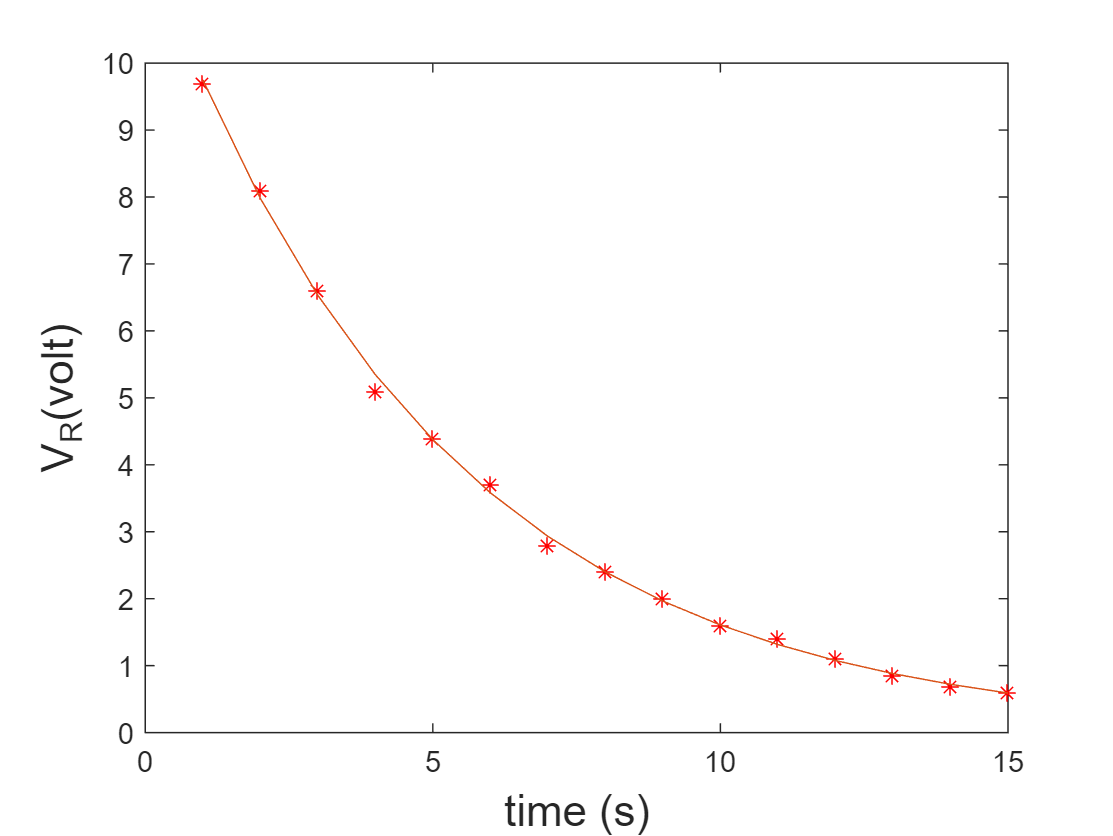

a0=Zopt(2);
a1=Zopt(1);
V0=exp(a0);
tau=-1/a1;
C=tau/R;


Yopt=V0*exp(-1/(R*C).*Xdata);

figure
plot(Xdata,Ydata, '*r')
hold on
plot(Xdata,Yopt)
hold on
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)

# 1st order ODE-IVP

## Problem

Solve for the response of an RC circuit with a DC  input 

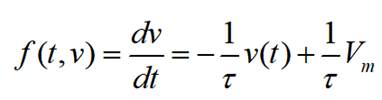

tau=  4.9919;   T=1/tau;  Vm=11.91;

Parameter Definitions

clear
close all
a=0; b=15; 
h=1; 

% Initial Condition

Eigvalue and vector of A (MATLAB):


y0 = 11.91;

eigVec =     0.1780   -0.0689
   -0.9840    0.9976


eigVa =    -5.5279         0
         0  -14.4721


t=a:h:b;
%x(1) = a;  
ytrue(1) = y0;
N = (b-a)/h;

### ode45()

%% MATLAB's function ODE45
[tmat,vmat] = ode45(@myRC, [a b], y0);  % Fourth/Fifth RK
figure()
plot(tmat,vmat,'.b')
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)

The RC function is defined in @myRC(t,v)

% function dvdx = myRC(v)
%    tau=4.9919; T=1/tau;  Vm=11.91;
%    dvdx =-T*v + 1*T*Vm;
% end


# Eigenvalue 

What are the eigenvalues for the given m-c-k system response? 

Use  m=10kg ; k=800 N/m; c=200 N/(m/s) 

clear; close all;

k=800; c=200; m=10;
A = [0 1; -k/m, -c/m];

disp('Eigvalue and vector of A (MATLAB):');
[eigVec,eigVa]=eig(A)


# ODE 2nd order 

Example of solving an m-c-k system with a sinusoidal input

The function is defined in mckFun.m

Use  m=10kg ; k=800 N/m; c=200 N/(m/s), f=10Hz , h=0.01

F_{dc}=100*cos(2*pi*f*t);

Parameter Definition

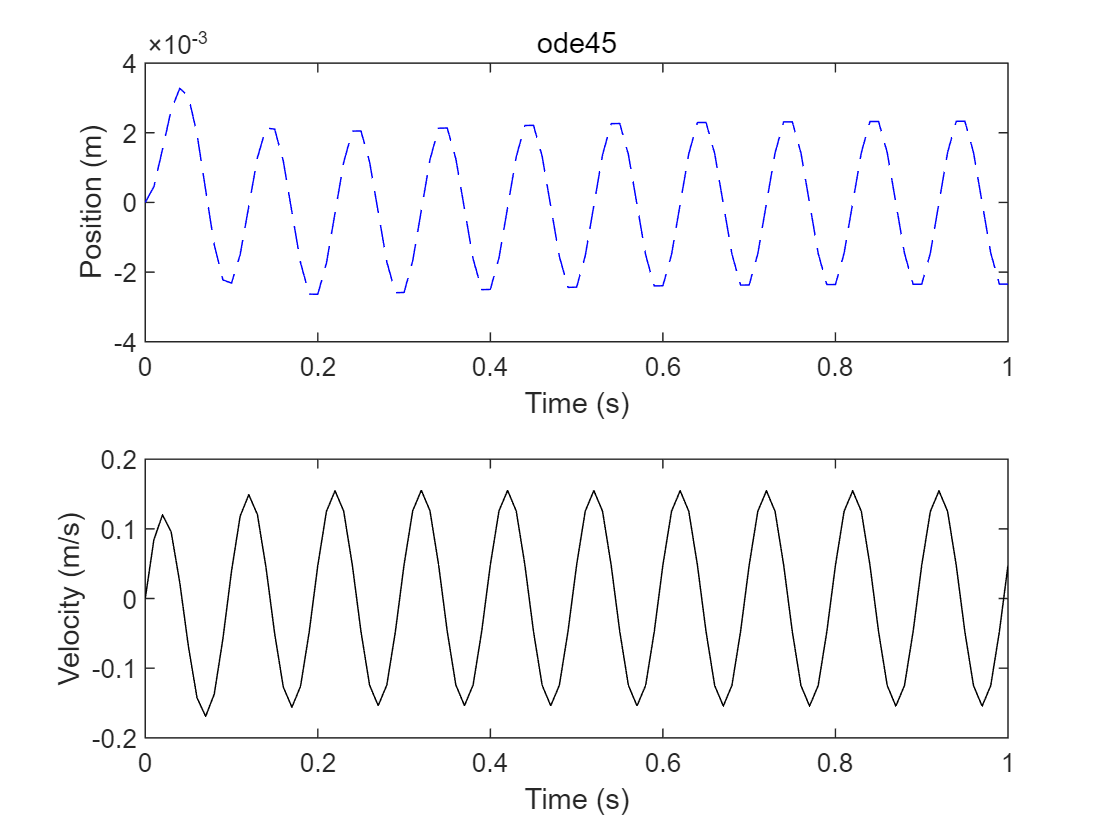


close all

yINI = 0;
vINI = 0;
a=0;

b=1;
h=0.01;
N = (b-a)/h;


## ode45()

tspan = [a:h:b];
yini = [yINI vINI];
[Time Y] = ode45(@mckFunc,tspan,yini);

figure
subplot(2,1,1)
    plot(Time,Y(:,1),'--b')
    xlabel('Time (s)')
    ylabel('Position (m)')
    title('ode45')
subplot(2,1,2)
    plot(Time,Y(:,2),'k')
    xlabel('Time (s)')
    ylabel('Velocity (m/s)')

function [dXdt] = mckFunc(t,x)
    dXdt=zeros(2,1); % column vector
    m=10; k=800; c=200; f=10;
    FinDC=100;

    Fin=FinDC*cos(2*pi*f*t);
    dXdt(1)=x(2);
    dXdt(2)=1/m*(Fin-c*x(2)-k*x(1));
end


The RC function is defined in @myRC(t,v)

function dvdx = myRC(t,v)
   tau=4.9919; T=1/tau;  Vm=0;
   dvdx =-T*v + 1*T*Vm;
end
